# Exercise 4 regbot

## Plot data from the log txt file

data = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_4\regbot_log_4.txt');
data = fillmissing(data, 'nearest');

data2 = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_4\regbot_log_4_2.txt');
data2 = fillmissing(data2, 'nearest');


t = table2array(data(:,1));     % time stamps
u_L = table2array(data(:,8));   % left motor voltage
u_R = table2array(data(:,9));   % right motor voltage
v_L = table2array(data(:,10));  % left motor velocity 
v_R = table2array(data(:,11));  % right motor velocity
T_s = t(2) - t(1);              % compute sampling time

%{
t = table2array(data2(:,1));    
u_L = table2array(data2(:,2));   
u_R = table2array(data2(:,3));   
v_L = table2array(data2(:,4));  
v_R = table2array(data2(:,5)); 
T_s = t(2) - t(1);   
%}           

%Trim data
% Find the index where X becomes 3 for the first time

idx = find(u_L >= 4,1,'first');
idx = idx - 20

idx = 731

% Keep only the data after this index
u_L = u_L(idx:end); 
v_L = v_L(idx:end);
u_R = u_R(idx:end); 
v_R = v_R(idx:end);
% Do the same for the time vector
t = t(idx:end);                 
t = t - t(1);

vel = 1/2*(v_L + v_R);          % average wheel velocity
volt = 1/2*(u_L + u_R);         % average voltage

idd_L = iddata(v_L,u_L,T_s);    % Prepare left wheel data
idd_R = iddata(v_R,u_R,T_s);    % Prepare right wheel data
idd_A = iddata(vel,volt,T_s);    % Prepare average wheel data

G_wu_L = tfest(idd_L,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_L =
 
  From input "u1" to output "y1":
         327.9
  --------------------
  s^2 + 96.08 s + 1093
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_L".
Fit to estimation data: 81.48%                    
FPE: 0.0001974, MSE: 0.0001947                    


G_wu_R = tfest(idd_R,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_R =
 
  From input "u1" to output "y1":
        530.3
  ------------------
  s^2 + 122 s + 1636
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_R".
Fit to estimation data: 85.38%                    
FPE: 0.0001179, MSE: 0.0001163                    


G_wu_A = tfest(idd_A,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_A =
 
  From input "u1" to output "y1":
         368.9
  --------------------
  s^2 + 97.43 s + 1182
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_A".
Fit to estimation data: 83.75%                    
FPE: 0.0001484, MSE: 0.0001463                    


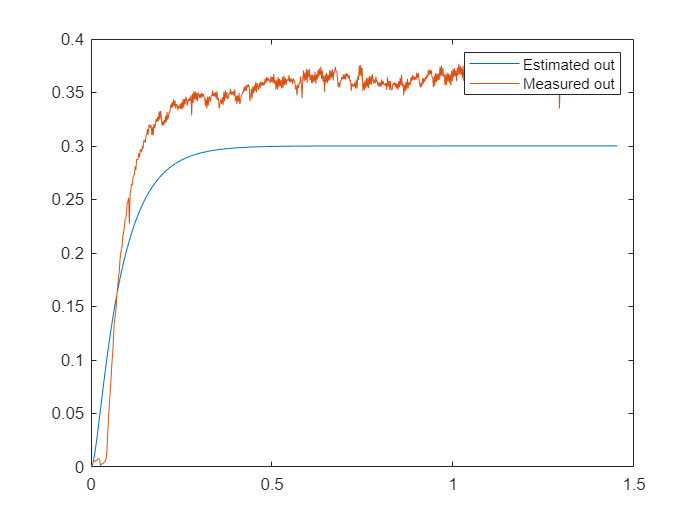

v_L_out = v_L - v_L(1);

[y_L,t_L] = step(G_wu_L,t(end));
plot(t_L,y_L);
hold on;
plot(t,v_L_out);
hold off;
legend('Estimated out','Measured out');

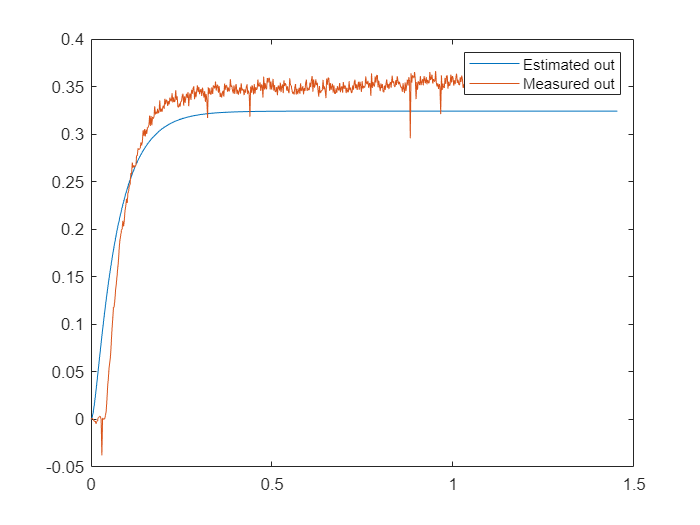


v_R_out = v_R - v_R(1);

[y_R,t_R] = step(G_wu_R,t(end));
plot(t_R,y_R);
hold on;
plot(t,v_R_out);
hold off;
legend('Estimated out','Measured out');

v_A_out = vel - vel(1)

v_A_out =          0
    0.0014
    0.0012
    0.0025
    0.0020
    0.0014
    0.0020
    0.0009
    0.0019
    0.0030


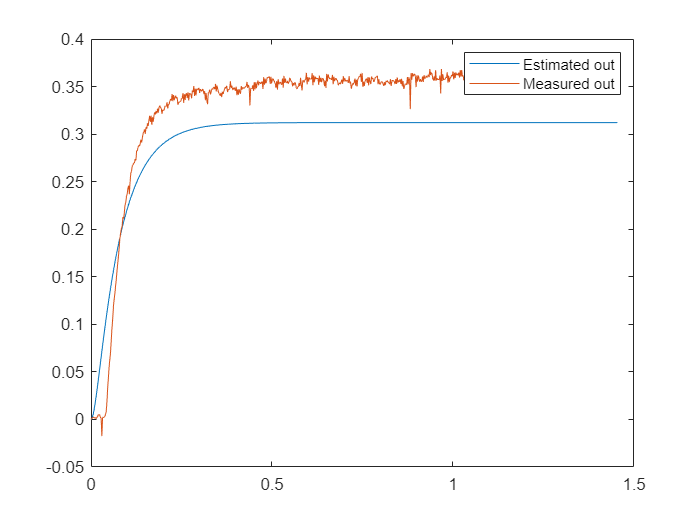


[y_A,t_A] = step(G_wu_A,t(end));
plot(t_A,y_A);
hold on;
plot(t,v_A_out);
hold off;
legend('Estimated out','Measured out');

data_wd = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_4\log_01.txt');
data_wd = fillmissing(data_wd, 'nearest');

t = table2array(data_wd(:,1))    % time stamps

t =     0.0010
    0.0030
    0.0050
    0.0070
    0.0090
    0.0110
    0.0130
    0.0150
    0.0170
    0.0190


u_L = table2array(data_wd(:,2))   % left motor voltage

u_L =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


u_R = table2array(data_wd(:,3))  % right motor voltage

u_R =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


v_L = table2array(data_wd(:,4))  % left motor velocity 

v_L =          0
         0
         0
         0
    0.0903
    0.1647
    0.1647
    0.1774
    0.1981
    0.1623


v_R = table2array(data_wd(:,5))  % right motor velocity

v_R =          0
         0
         0
         0
         0
    0.1496
    0.1496
    0.2153
    0.2077
    0.2061


T_s = t(2) - t(1)              % compute sampling time

T_s = 0.0020

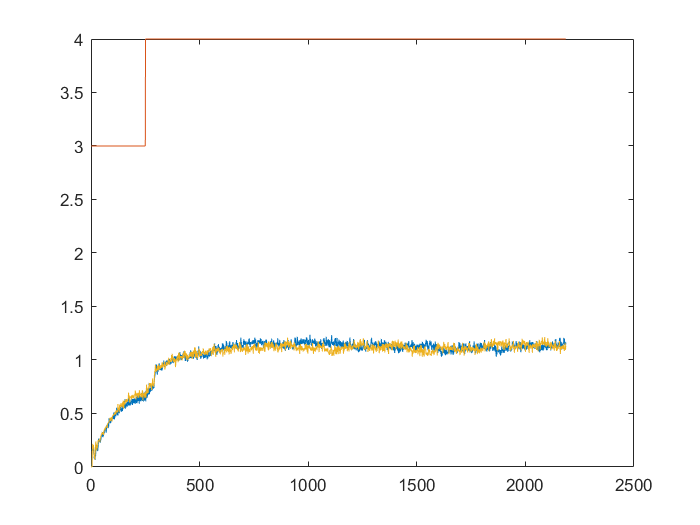


figure
plot(v_L)

hold on
plot(u_L)
plot(v_R)
hold off

idx = find(u_L >= 4,1,'first')

idx = 251

idx = idx + 42

idx = 293

t = t(idx:end);                 
t = t - t(1);

u_L = u_L(idx:end) 

u_L =      4
     4
     4
     4
     4
     4
     4
     4
     4
     4


v_L = v_L(idx:end)

v_L =     0.8439
    0.8525
    0.8682
    0.9004
    0.9007
    0.9092
    0.9566
    0.9592
    0.9425
    0.9548


u_R = u_R(idx:end)

u_R =      4
     4
     4
     4
     4
     4
     4
     4
     4
     4


v_R = v_R(idx:end)

v_R =     0.8849
    0.8987
    0.8990
    0.9352
    0.9532
    0.9142
    0.8885
    0.9098
    0.9062
    0.9148



vel = 1/2*(v_L + v_R)         % average wheel velocity

vel =     0.8644
    0.8756
    0.8836
    0.9178
    0.9269
    0.9117
    0.9225
    0.9345
    0.9244
    0.9348


volt = 1/2*(u_L + u_R)         % average voltage

volt =      4
     4
     4
     4
     4
     4
     4
     4
     4
     4



idd_A = iddata(v_L,u_L,T_s)    % Prepare average wheel data

idd_A =

Time domain data set with 1894 samples.
Sample time: 0.002 seconds              
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


      
G_wd_L = tfest(idd_A,2,0) % Identify wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wd_L =
 
  From input "u1" to output "y1":
          12.1
  ---------------------
  s^2 + 12.67 s + 42.81
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_A".
Fit to estimation data: 41.45%                    
FPE: 0.001048, MSE: 0.001043                      



v_A_out = vel - vel(1)

v_A_out =          0
    0.0112
    0.0192
    0.0534
    0.0625
    0.0473
    0.0581
    0.0701
    0.0599
    0.0704


v_L_out = v_L - v_L(1)

v_L_out =          0
    0.0086
    0.0243
    0.0565
    0.0568
    0.0653
    0.1127
    0.1153
    0.0986
    0.1109


v_R_out = v_R - v_R(1)

v_R_out =          0
    0.0138
    0.0141
    0.0503
    0.0683
    0.0293
    0.0036
    0.0249
    0.0213
    0.0299



[y_A,t_A] = step(G_wd_L,t(end))

y_A =          0
    0.0012
    0.0045
    0.0096
    0.0161
    0.0237
    0.0322
    0.0413
    0.0509
    0.0607


t_A =          0
    0.0146
    0.0291
    0.0437
    0.0583
    0.0728
    0.0874
    0.1020
    0.1165
    0.1311


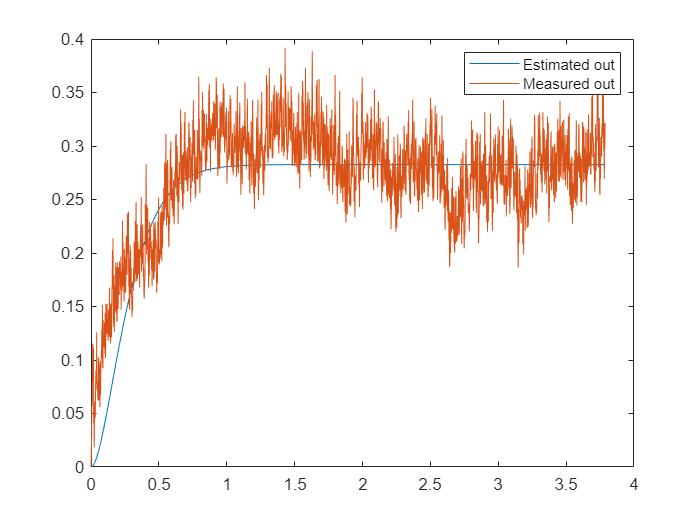

plot(t_A,y_A)
hold on;
plot(t,v_L_out)
hold off;
legend('Estimated out','Measured out')